% Rocky_closed_loop_poles_23.m
%
% 1) Symbolically calculates closed loop transfer function of a disturbannce
% rejection PI control system for Rocky. 
% No motor model (M =1). With motor model (1st order TF)
%
% 2) Specify location of (target)poles based on desired reponse. The number of
% poles = denominator polynomial of closed loop TF
%
% 3) Extract the closed loop denomiator poly and set = polynomial of target
% poles
%
% 4) Solve for Ki, Kp  to match coefficients of polynomials. In general,
% this will be underdefined and will not be able to place poles in exact
% locations. In this, the control constants can be found exactly 
%
% 5) Plot impulse and step response to see closed-loop behavior. 
%
% based on code by SG. last modified 2/25/23 CL

clear all; 
close all;

syms s a b l g Kp Ki    % define symbolic variables

Hvtheta = -s/l/(s^2-g/l);       % TF from velocity to angle of pendulum

K = Kp + Ki/s;                  % TF of the PI angle controller
M = a*b/(s+a)                   % TF of motor (1st order model) 

$$M = \frac{a\,b}{a+s}$$

%  M = 1;                       % TF without motor
%
%  
% closed loop transfer function from disturbance d(t)totheta(t)
Hcloop = 1/(1-Hvtheta*M*K)    % use this for no motor feedback

$$Hcloop = -\frac{1}{\frac{a\,b\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{l\,\left(\frac{g}{l}-s^{2}\right)\,\left(a+s\right)}-1}$$


pretty(simplify(Hcloop))       % to display the total transfer function

              1
- ------------------------
     a b (Ki + Kp s)
  -------------------- - 1
                2
  (a + s) (- l s  + g)




% Substitute parameters and solve
% system parameters
g = 9.81;
l = 22*2.54/100   %effective length 

l = 0.5588

a = 14;           %nominal motor parameters
b = 1/400;        %nominal motor parameters

Hcloop_sub = subs(Hcloop) % sub parameter values into Hcloop

$$Hcloop\_sub = \frac{1}{\frac{175\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{2794\,\left(s^{2}-\frac{24525}{1397}\right)\,\left(s+14\right)}+1}$$


% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc. 
p1 = -2    % dominant pole pair

p1 = -2

p2 = -2   % dominant pole pair 

p2 = -2

p3 = -5

p3 = -5



% target characteristic polynomial
% if motor model (TF) is added, order of polynomial will increases
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)

$$tgt\_char\_poly = {\left(s+2\right)}^{2}\,\left(s+5\right)$$

npoly = 3

npoly = 3



% get the denominator from Hcloop_sub
[n d] = numden(Hcloop_sub)

$$n = 2\,\left(1397\,s^{2}-24525\right)\,\left(s+14\right)$$

$$d = 175\,\mathrm{Ki}-49050\,s+175\,\mathrm{Kp}\,s+39116\,s^{2}+2794\,s^{3}-686700$$


% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s)

$$coeffs\_denom = \left(\begin{array}{cccc} 175\,\mathrm{Ki}-686700 & 175\,\mathrm{Kp}-49050 & 39116 & 2794 \end{array}\right)$$


% divide though the coefficient of the highest power term
coeffs_denom = coeffs(d, s)/(coeffs_denom(end))

$$coeffs\_denom = \left(\begin{array}{cccc} \frac{175\,\mathrm{Ki}}{2794}-\frac{343350}{1397} & \frac{175\,\mathrm{Kp}}{2794}-\frac{24525}{1397} & 14 & 1 \end{array}\right)$$


% find coefficients of the target charecteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s)

$$coeffs\_tgt = \left(\begin{array}{cccc} 20 & 24 & 9 & 1 \end{array}\right)$$


% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom(1:npoly-1) == coeffs_tgt(1:npoly-1),  Kp, Ki)

solutions = struct with fields:
    Kp: [1×1 sym]
    Ki: [1×1 sym]



% display the solutions as double precision numbers
Kp = double(solutions.Kp)

Kp = 663.4629

Ki = double(solutions.Ki)

Ki = 4.2433e+03


% reorder coefficients for the check polynomial 
for ii = 1:length(coeffs_denom)
    chk_coeffs_denom(ii) = coeffs_denom(length(coeffs_denom) + 1 - ii);
end
closed_loop_poles = vpa (roots(subs(chk_coeffs_denom)), npoly )

$$closed\_loop\_poles = \left(\begin{array}{c} -12.2\\ -0.919-0.894\,\mathrm{i}\\ -0.919+0.894\,\mathrm{i} \end{array}\right)$$



% Plot impulse response of closed-loop system
    TFstring = char(subs(Hcloop));
    % Define 's' as transfer function variable
    s = tf('s');
    % Evaluate the expression
    eval(['TFH = ',TFstring]);

TFH =
 
  3.072e15 s^4 + 4.301e16 s^3 - 5.393e16 s^2 - 7.55e17 s
  -------------------------------------------------------
  3.072e15 s^4 + 4.301e16 s^3 + 7.373e16 s^2 + 6.144e16 s
 
Continuous-time transfer function.



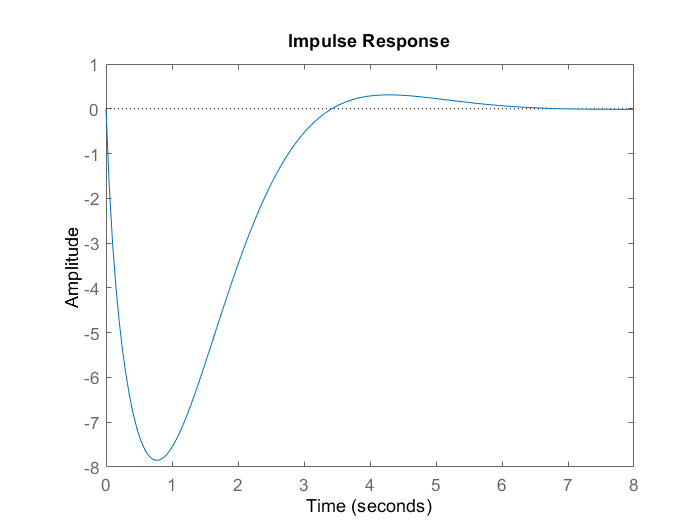

    figure (1)
    impulse(TFH);   %plot the impulse reponse

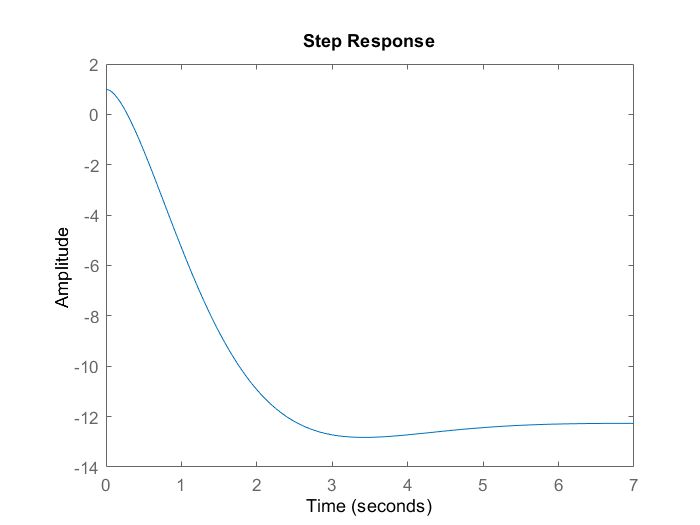

    figure(2)
    step(TFH)       %plot the step response